addpath('Classes')
addpath('Simulink Models/Simulation')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

clear FSFB_Int
clear FSFB_PID
clear FSFB_FF

# Lock-Step Euclidean Distance Trajectory Study

This script simulates several trajectory tracking controllers for different types of periodic setpoints at various frequencies. For each type of trajectory, it plots the lock-step Euclidean distance measure for each controller against the frequency of the periodic setpoint.

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 
  
%Choose a plant model symbolic variable to create a matlab function block from

% plant_model = Lnrzed_EOMs.Lin_EOMs; %Choose the linear decoupled model of the plant.
plant_model = rhs(BP_Kinetics.NL_NumEOMs); %Choose the coupled nonlinear model as the plant. Torques still approximated


if (~exist('FSFB_PID', 'var'))

    FSFB_PID = Lin_FSFB_Cntrl(Lnrzed_EOMs, plant_model, VDefs, 'FSFB PID Controller');

end

if (~exist('FSFB_FF', 'var'))

    FSFB_FF = Lin_FSFB_Cntrl(Lnrzed_EOMs, plant_model, VDefs, 'FSFB FF Controller');

end

For now, I am going to rely on running the scripts associated with each controller and having the controller objects available. I really need to make the SISO sliding mode into a class. I might also want to just have the FSFB classes take in Q and R matrices instead of having to generate the gain matrices each time I want to run the simulations. But then that makes it difficult to simply alter the K matrices if I want to. It's a tough thing to find a balance on. 

## FSFB with Feed Forward

%Specify initial conditions and compute initial outputs
x_0 = 1/2*[r_sim; 0; 0; 0; r_sim; 0; 0; 0];

%First order smoothing with time constant Tau
Tau = 2; 

%Sets the number of simulations we run for each different type of rose curve
T = linspace(3, 10, 10);

T =     3.0000    3.7778    4.5556    5.3333    6.1111    6.8889    7.6667    8.4444    9.2222   10.0000


### Quadrifolium

%Which rose curve to simulate many times?
n = 2; %Selects a rose curve
d = 1; %Selects a rose curve
k = n/d; 

%Allocate memory for the LSED measures of the feed-forward controller, quadrifolium
%responses
qdflm_LSED_FF = zeros(1,length(T));

%Quadrifolium loop
for m = 1:length(T)

    %Ideal trajectory parameters
    r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide
    
    %Rose curve specified by k
    tot_period = T(m); %this many seconds before the entire rose curve loops around
    omega_sim = omega_rose(tot_period,n,d);
    des_traj_sym_x(VDefs.t) = r_sim/2*(cos((k+1)*omega_sim*VDefs.t) + cos((k-1)*omega_sim*VDefs.t));
    des_traj_sym_y(VDefs.t) = r_sim/2*(sin((k+1)*omega_sim*VDefs.t) - sin((k-1)*omega_sim*VDefs.t));

    %Specify simulation time
    tspan = [0 tot_period*3];

    FSFB_FF.Run_Sim(des_traj_sym_x, des_traj_sym_y, tspan, x_0,Tau, K_FF1, K_FF2);

    %Want to look at steady-state response only
    i_LSED = (FSFB_FF.sim_response.tout>=2*tot_period) & (FSFB_FF.sim_response.tout<=3*tot_period);
    
    %Get the data for use with the LSED measure
    x = FSFB_FF.sim_response.x(i_LSED,1);
    y = FSFB_FF.sim_response.x(i_LSED,5);
    x_s = FSFB_FF.sim_response.x_s_vec(i_LSED,1);
    y_s = FSFB_FF.sim_response.y_s_vec(i_LSED,1);

    %Compute LSED
    qdflm_LSED_FF(m) = LSED(30, [x, y], [x_s y_s], FSFB_FF.sim_response.tout(i_LSED));

end

tot_period = 3

tot_period = 3.7778

tot_period = 4.5556

tot_period = 5.3333

tot_period = 6.1111

tot_period = 6.8889

tot_period = 7.6667

tot_period = 8.4444

tot_period = 9.2222

tot_period = 10

## FSFB PID

%Specify initial conditions and compute initial outputs
x_0 = 1/2*[r_sim; 0; 0; 0; r_sim; 0; 0; 0];

%First order smoothing with time constant Tau
Tau = 2; 

%Sets the number of simulations we run for each different type of rose curve
T = linspace(3, 10, 10);

T =     3.0000    3.7778    4.5556    5.3333    6.1111    6.8889    7.6667    8.4444    9.2222   10.0000


### Quadrifolium

%Which rose curve to simulate many times?
n = 2; %Selects a rose curve
d = 1; %Selects a rose curve
k = n/d; 

%Allocate memory for the LSED measures of the feed-forward controller, quadrifolium
%responses
qdflm_LSED_PID = zeros(1,length(T));

%Quadrifolium loop
for m = 1:length(T)

    %Ideal trajectory parameters
    r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide
    
    %Rose curve specified by k
    tot_period = T(m) %this many seconds before the entire rose curve loops around
    omega_sim = omega_rose(tot_period,n,d);
    des_traj_sym_x(VDefs.t) = r_sim/2*(cos((k+1)*omega_sim*VDefs.t) + cos((k-1)*omega_sim*VDefs.t));
    des_traj_sym_y(VDefs.t) = r_sim/2*(sin((k+1)*omega_sim*VDefs.t) - sin((k-1)*omega_sim*VDefs.t));

    %Specify simulation time
    tspan = [0 tot_period*3];

    FSFB_PID.Run_Sim(des_traj_sym_x, des_traj_sym_y, tspan, x_0,Tau, K_PID1, K_PID2);

    %Want to look at steady-state response only
    i_LSED = (FSFB_PID.sim_response.tout>=2*tot_period) & (FSFB_PID.sim_response.tout<=3*tot_period);
    
    %Get the data for use with the LSED measure
    x = FSFB_PID.sim_response.x(i_LSED,1);
    y = FSFB_PID.sim_response.x(i_LSED,5);
    x_s = FSFB_PID.sim_response.x_s_vec(i_LSED,1);
    y_s = FSFB_PID.sim_response.y_s_vec(i_LSED,1);

    %Compute LSED
    qdflm_LSED_PID(m) = LSED(30, [x, y], [x_s y_s], FSFB_PID.sim_response.tout(i_LSED));

end

### Plot Quadriofolium Results

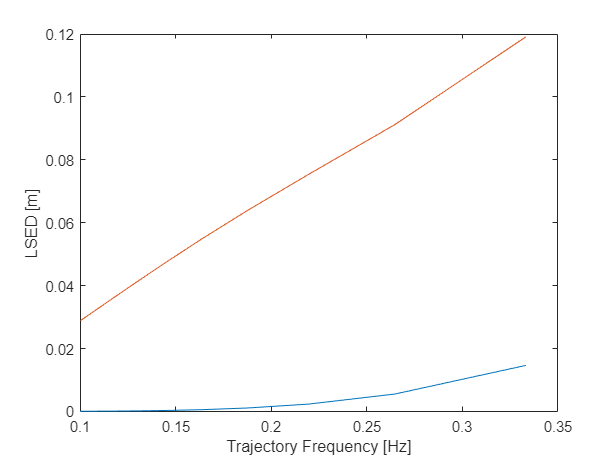

figure
plot(1./T, qdflm_LSED_FF, 1./T, qdflm_LSED_PID)
xlabel('Trajectory Frequency [Hz]')
ylabel('LSED [m]')